Tommaso Borelli (251831)

Francesco Jin (273941)

Maria Chiara Lischi (271281)

Nadeer Salem (274491)

**Task 1**

1. Import the dataset in MATLAB. Store the vectors of observations of the response variable and each of the regressors in separate MATLAB variables.

Concretedata

Concretedata = 1.0e+03 *

    0.2980    0.2100    0.8800    0.7440    0.0319
    0.1819    0.1857    1.0124    0.7143    0.0124
    0.1399    0.2003    0.9160    0.7534    0.0364
    0.1907    0.1621    1.0900    0.8040    0.0406
    0.3138    0.1699    0.9253    0.7829    0.0385
    0.2300    0.1955    1.0294    0.7586    0.0315
    0.3870    0.1570    0.9380    0.8450    0.0459
    0.1548    0.1933    0.8772    0.8677    0.0238
    0.2297    0.1952    1.0281    0.7576    0.0134
    0.5220    0.1460    0.8960    0.8960    0.0750


data = Concretedata;

X_train = data(1:95,1:4);
Y_train = data(1:95,5);
X_test = data(96:100,1:4);
Y_test = data(96:100,5);

2. We are now generating the four distinct scatterplots of the response variable vs. each of the regressors

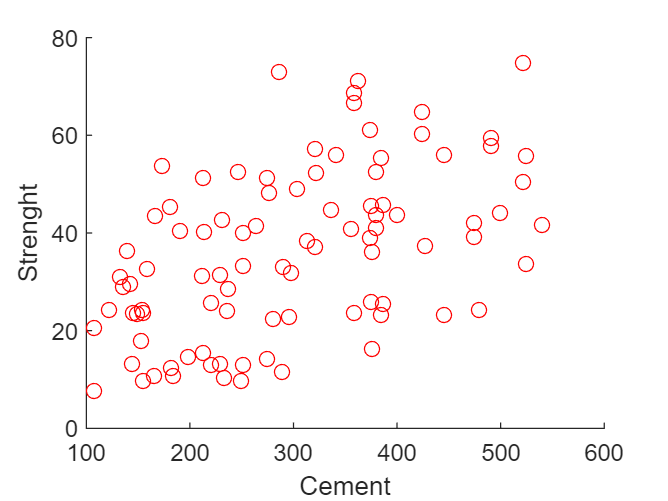

labels = ["Cement", "Water", "Coarse Aggregate", "Fine Aggregate", "Strenght"];
Colours = ["Red", "Cyan", "Green", "Blue"];
figure

scatter(X_train(:,1) , Y_train, Colours(1))
xlabel(labels(1,1));
ylabel(labels(1,5));

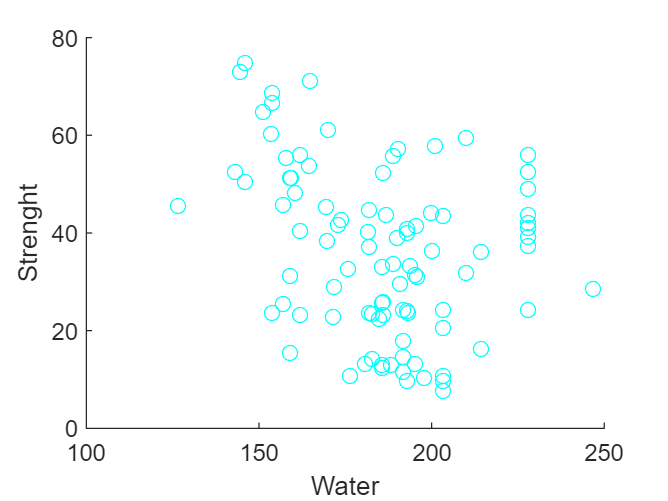


scatter(X_train(:,2) , Y_train, Colours(2))
xlabel(labels(1,2));
ylabel(labels(1,5));

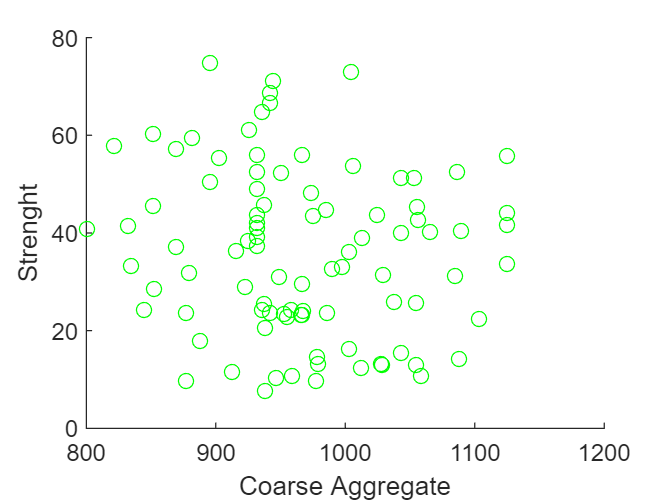


scatter(X_train(:,3) , Y_train, Colours(3))
xlabel(labels(1,3));
ylabel(labels(1,5));

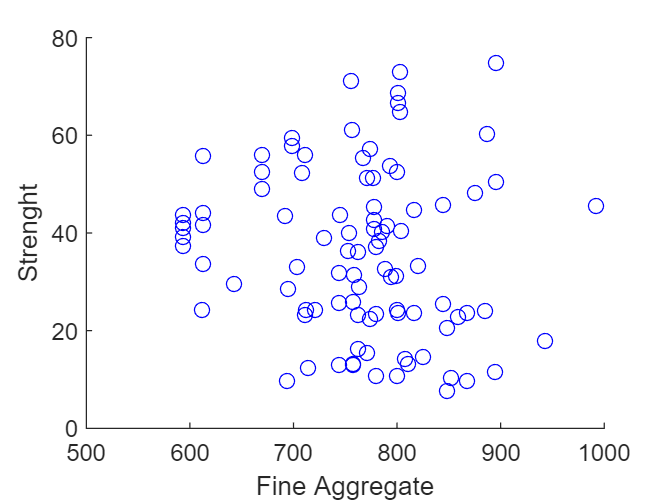


scatter(X_train(:,4) , Y_train, Colours(4))
xlabel(labels(1,4));
ylabel(labels(1,5));

4. Consider four distinct linear models, one for each pair response variable-regressor. Compute in MATLAB the coeficients of the linear models that best fit the data.

beta_hat =    15.1382
    0.0697


Cement


The root mean square error is: 14.547


beta_hat =    74.3013
   -0.2045


Water


The root mean square error is: 15.986


beta_hat =    64.9969
   -0.0297


Coarse Aggregate


The root mean square error is: 16.562


beta_hat =    55.2837
   -0.0250


Fine Aggregate


The root mean square error is: 16.580


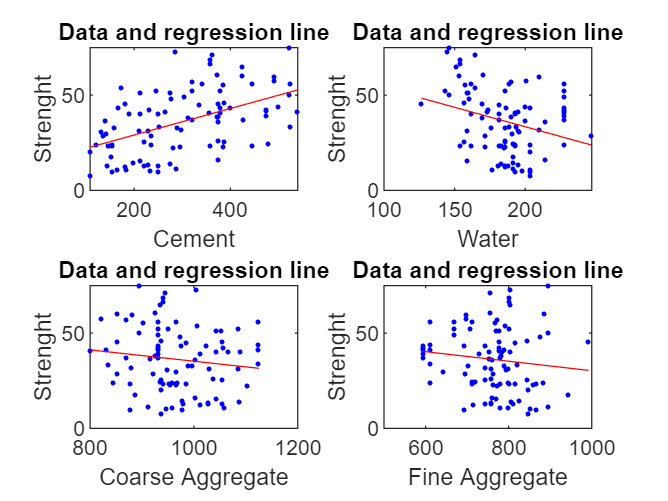

for c = 1:4
    m = length(X_train(:,c));
    X = [ones(m,1) X_train(:,c)];
    beta_hat = inv(X.'*X)*X.'*Y_train 
    fitted_v = X*beta_hat;

5. In MATLAB, plot the regression line on each of the corresponding scatterplots previously generated.

    subplot(2,2,c)
    plot(X_train(:,c),Y_train,'b.','DisplayName','Data')
    hold on
    plot(X_train(:,c),fitted_v, 'r-', 'DisplayName','Regr. line')
    xlabel(labels(c))
    ylabel(labels(5))
    title('Data and regression line')


For the new observations we obtain the following predictions:


Using Cement as a predictor: 48.403
Using Water as a predictor: 51.058
Using Coarse Aggregate as a predictor: 48.019
Using Fine Aggregate as a predictor: 45.601
Using Strenght as a predictor: 48.019


While the real value of the strenght of the concrete sample was: 24.497


For the new observations we obtain the following predictions:


Using Cement as a predictor: 50.705
Using Water as a predictor: 51.322
Using Coarse Aggregate as a predictor: 51.078
Using Fine Aggregate as a predictor: 51.356
Using Strenght as a predictor: 51.078


While the real value of the strenght of the concrete sample was: 7.398


For the new observations we obtain the following predictions:


Using Cement as a predictor: 28.063
Using Water as a predictor: 28.243
Using Coarse Aggregate as a predictor: 31.236
Using Fine Aggregate as a predictor: 31.816
Using Strenght as a predictor: 31.236


While the real value of the strenght of the concrete sample was: 22.504


For the new observations we obtain the following predictions:


Using Cement as a predictor: 35.068
Using Water as a predictor: 35.365
Using Coarse Aggregate as a predictor: 33.642
Using Fine Aggregate as a predictor: 34.142
Using Strenght as a predictor: 33.642


While the real value of the strenght of the concrete sample was: 36.839


7. Compute in MATLAB the root mean square error (RMSE) for each of the models previously obtained. Discuss the values obtained in the report and use them to try to make a comparison between the linear models obtained.

    lse = norm(Y_train - fitted_v); 
    rss = lse^2; 
    mse = rss/m; 

beta_hat_4 =   237.7899
    0.0423
   -0.4218
   -0.0719
   -0.0870


    rmse = sqrt(mse); 
    disp(sprintf('%s',labels(c)))
    disp(sprintf('The root mean square error is: %.3f', rmse))
    disp(sprintf('%s'," "))
    hold off
end


8. Try to use the linear models obtained to make some predictions using possible new observations of the regressors. What can you say about the reliability of the predictions? Provide some comments in the report.

for c = 1:4
    m_new = length(X_test(:,c));

beta_hat_3 =    92.9009
    0.0669
   -0.2172
   -0.0377


    X_new = [ones(m_new,1) X_test(:,c)];
    prediction = X_new*beta_hat;
    disp('For the new observations we obtain the following predictions:')
    for i = 1:5
        disp(sprintf('Using %s as a predictor: %.3f', labels(i), prediction(i)))
    end
    disp(sprintf('While the real value of the strenght of the concrete sample was: %.3f', Y_test(c,:)))
    disp(sprintf(' '))
end

cement =   108.3000
  108.3000
  122.6000
  133.0000
  136.0000
  139.9000
  143.0000
  144.8000
  146.0000
  149.0000


**Task 2**

1. Consider the linear model with all four predictor variables in your dataset. Compute in MATLAB the coeficients of the linear models that best fit the data.

m = length(Y_train);

stren =    20.5940
    7.7235
   24.2909
   31.0264
   29.0683
   36.4436
   29.7233
   13.2021
   23.7387
   23.5180


X = [ones(m,1) X_train];
beta_hat_4 = X\Y_train

p2_c =    -0.0001    0.1477    3.7160


fitted_tot = X*beta_hat_4;

p3_c =    -0.0000    0.0004   -0.0090   17.3742


3. Given the linear model obtained above and considering the comments made in Task 1 on the linear models with a single predictor, try to propose other possible linear models where you use two or three predictor variables. Motivate in the report your decision on which predictor variables you have selected. 

looking at the previous linear model and our currenr predictors we are proposing a linear model with three predictors: Cement  it is the only variable having a positive effect on the responce; Water since it has the strongest effect overall and seemes, as shown by its previos model, to have a strong positive effect on the responce; we deided to use coarse instead of fine aggregate due to the following reasons:

- has a lower RMSE than the other aggregate : 16.56 rather than 16.58

- in task one point 8, 'Coarse' presented better results in comparison with 'fine'

- has  lesser negative effect on our current Multiple linear regression model.

4. Compute in MATLAB the coeficients of the linear models proposed in point 3. that best fit the data and include them in the report.

regressors_3 = X_train(:,[1,2,3]);

p4_c =     0.0000   -0.0000    0.0047   -0.7945   67.2490


X = [ones(m,1) regressors_3];
beta_hat_3 = X\Y_train
fitted_v = X*beta_hat_3;


5. Look at scatterplots obtained in Task 1. Is it reasonable to consider general linear models for some of the pairs predictor-response variable, where the relationship between these variables is non-linear? If so, propose possible models, motivating your decision in the report

6. Compute in MATLAB the coedicients of the models proposed in point 5. that best fit the data. **Cement**

x_c = Concretedata(:,[1 5]);

Rsqr2_c = 0.2594

x_c = sortrows(x_c,1);

Rsqr3_c = 0.2617

cement = x_c(:,1)

Rsqr4_c = 0.2665

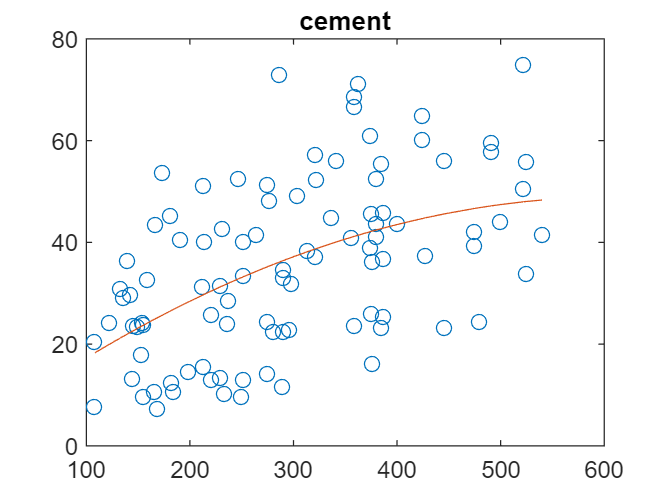

stren = x_c(:,2)

p2_c = polyfit(cement, stren, 2)
p3_c = polyfit(cement, stren, 3) 
p4_c = polyfit(cement, stren, 4)

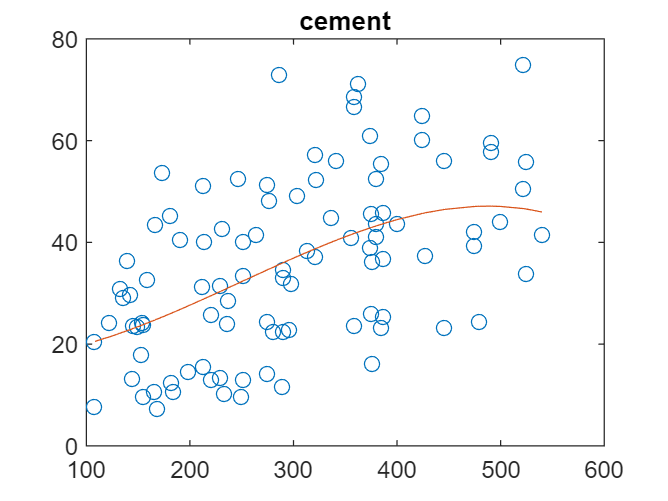


f2_c = polyval(p2_c,cement); 
f3_c = polyval(p3_c,cement);  
f4_c = polyval(p4_c,cement); 

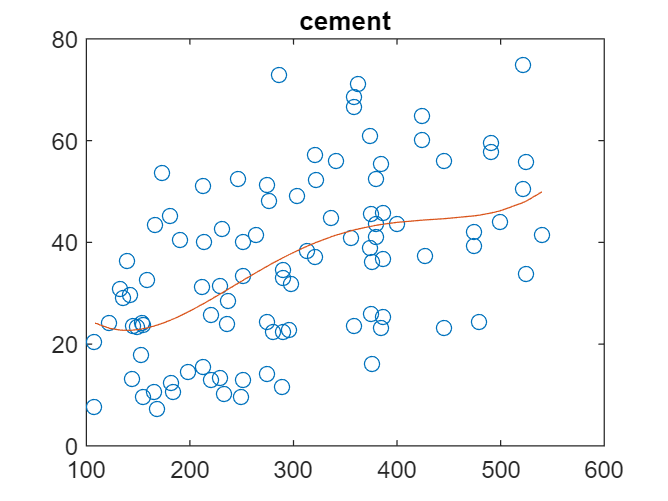

  
 

Rsqr2_c = 1 - sum((stren - f2_c).^2)/sum((stren- mean(stren)).^2)
Rsqr3_c = 1 - sum((stren - f3_c).^2)/sum((stren- mean(stren)).^2)

Rsqr4_c = 1 - sum((stren - f4_c).^2)/sum((stren- mean(stren)).^2)

7. In MATLAB, plot the curve that fits the data on each of the corresponding scatterplots for the models proposed in point 5.


figure
plot(cement,stren,'o',cement,f2_c,'-') 
title('cement') 

water =   126.6000
  143.3000
  144.7000
  146.0000
  146.0000
  151.4000
  153.5000
  154.0000
  154.0000
  154.0000


stren =    45.6985
   52.5036
   72.9948
   74.9874
   50.5110
   64.9004
   60.2947
   68.7506
   23.6392
   66.7807


figure
plot(cement,stren,'o',cement,f3_c,'-') 

p2_w =     0.0087   -3.4426  369.8314


title('cement') 

p3_w =     0.0000   -0.0071   -0.5213  192.1840


p4_w = 1.0e+03 *

   -0.0000    0.0000   -0.0010    0.1156   -4.9873



figure
plot(cement,stren,'o',cement,f4_c,'-') 
title('cement') 



6. Compute in MATLAB the coedicients of the models proposed in point 5. that best fit the data. **Water**

x_w = Concretedata(:,[2 5]);

Rsqr2_w = 0.2095

x_w = sortrows(x_w,1);

Rsqr3_w = 0.2110

water = x_w(:,1)

Rsqr4_w = 0.2706

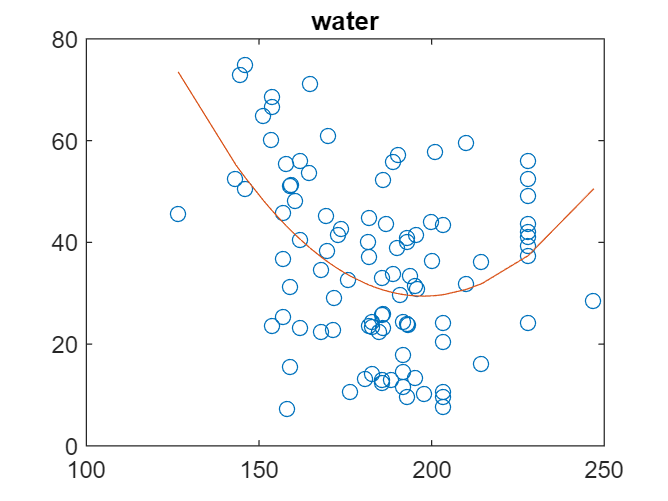

stren = x_w(:,2)

p2_w = polyfit(water, stren, 2)
p3_w = polyfit(water, stren, 3) 
p4_w = polyfit(water, stren, 4)

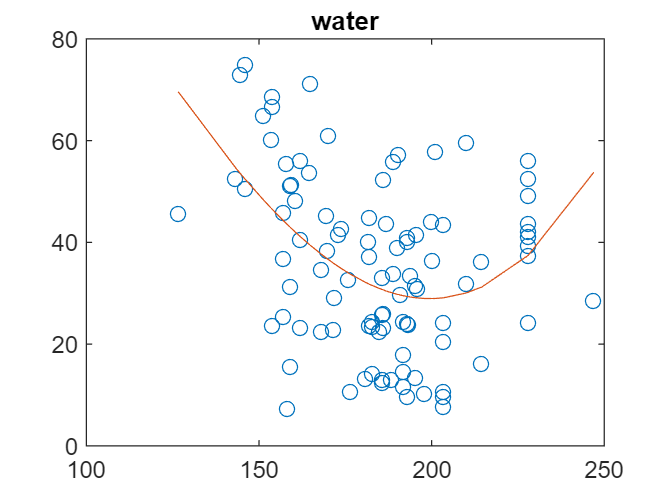


f2_w = polyval(p2_w,water); 
f3_w = polyval(p3_w,water);  
f4_w = polyval(p4_w,water); 

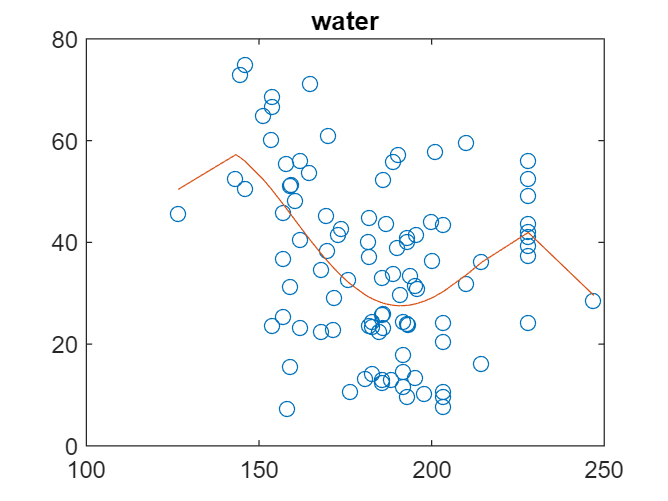

  
 

Rsqr2_w = 1 - sum((stren - f2_w).^2)/sum((stren- mean(stren)).^2)

Rsqr3_w = 1 - sum((stren - f3_w).^2)/sum((stren- mean(stren)).^2)
Rsqr4_w = 1 - sum((stren - f4_w).^2)/sum((stren- mean(stren)).^2)


7. In MATLAB, plot the curve that fits the data on each of the corresponding scatterplots for the models proposed in point 5.

figure
plot(water,stren,'o',water,f2_w,'-') 
title('water') 


rmse1 = 12.7474

figure
plot(water,stren,'o',water,f3_w,'-') 
title('water') 

figure
plot(water,stren,'o',water,f4_w,'-') 

rmse2 = 13.5245

title('water') 

9. Compute in MATLAB the root mean square error (RMSE) for each of the models considered previously. Discuss the values obtained in the report and use them to try to make a comparison between the linear models.

m = length(X_train);
lse1 = norm(Y_train - fitted_tot); 
rss1 = lse1^2; 
mse1 = rss1/m; 
rmse1 = sqrt(mse1)

rmse3 = 21.0045



lse2 = norm(Y_train - fitted_v); 
rss2 = lse2^2;
mse2 = rss2/m;
rmse2 = sqrt(mse2)

rmse4 = 14.2019



m = length(cement);
lse3 = norm(stren - f4_c); 
rss3 = lse3^2;

predictors = 1.0e+03 *

    0.2980    0.2100    0.8800    0.7440
    0.1819    0.1857    1.0124    0.7143
    0.1399    0.2003    0.9160    0.7534
    0.1907    0.1621    1.0900    0.8040
    0.3138    0.1699    0.9253    0.7829
    0.2300    0.1955    1.0294    0.7586
    0.3870    0.1570    0.9380    0.8450
    0.1548    0.1933    0.8772    0.8677
    0.2297    0.1952    1.0281    0.7576
    0.5220    0.1460    0.8960    0.8960


mse3 = rss3/m;

m = 100

n = 4

rmse3 = sqrt(mse3)


S = 1.0e+04 *

    1.3631   -0.0070   -0.0670   -0.3408
   -0.0070    0.0565   -0.0361   -0.1187
   -0.0670   -0.0361    0.5599   -0.1112
   -0.3408   -0.1187   -0.1112    0.6935


m = length(water);

P =    -0.0685    0.2741   -0.2666   -0.9215
   -0.9643   -0.2479    0.0886   -0.0277
   -0.1202    0.7123    0.6912    0.0208
   -0.2257    0.5967   -0.6658    0.3869


D = 1.0e+04 *

    0.0237
    0.4535
    0.6882
    1.5075


lse4 = norm(stren - f4_w); 

ans =     1.0000    0.0000         0    0.0000
    0.0000    1.0000         0    0.0000
         0         0    1.0000         0
    0.0000    0.0000         0    1.0000


rss4 = lse4^2;

ans = 1.0e-11 *

         0   -0.0512   -0.1364    0.0909
   -0.0512   -0.0568   -0.0512         0
   -0.1364   -0.0625         0   -0.2046
    0.0909   -0.0227   -0.1364    0.0909


mse4= rss4/m;
rmse4 = sqrt(mse4)


**Task 3**

1. Consider the data matrix whose columns are only the four predictor variables in your dataset. Compute in MATLAB the eigenvalues and the eigenvectors of the sample correlation matrix.

predictors = Concretedata(:,1:4)

eigval = 1.0e+04 *

    1.5075
    0.6882
    0.4535
    0.0237


[m,n] = size(predictors)

The function `cov` computes the sample variance matrix.

S = cov(predictors)
[P,D] = eig(S,'vector')
P.'*P
S-P*diag(D)*P.'

Ideally, the eigenvalue decomposition satisfies the relationship. Since `eig` performs the decomposition using floating-point computations, then `A*V` can, at best, approach `V*D`. In other words, `A*V - V*D` is close to, but not exactly, `0`.

2. Determine in MATLAB the proportion of total sample variance explained by each of the sample principal components and draw the scree plot.

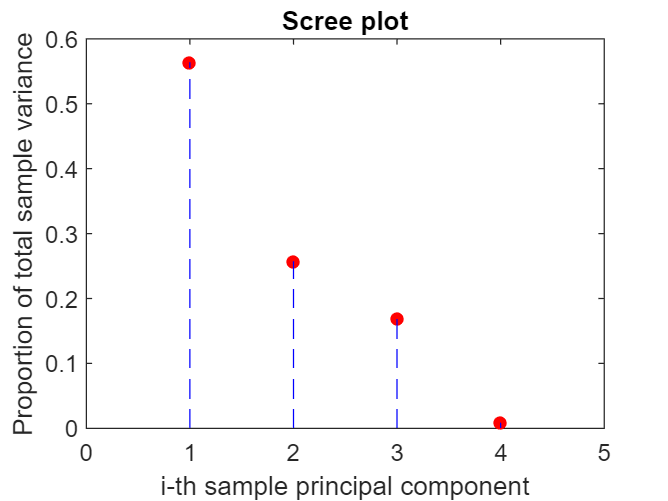

eigval = sort(D,'descend')
totalvar = sum(eigval);
prop = eigval./totalvar; 

figure();
plot(1:n,prop,'r.','MarkerSize',16)
xlim([0 n+1]);
hold on
for k = 1:n
    N = 100;
    x = k*ones(N);

    y = linspace(0,prop(k),N);
    plot(x,y,'b--')
end
xlabel('i-th sample principal component')
ylabel('Proportion of total sample variance')
title('Scree plot')

3. For each i = 1, . . . , 4, compute in MATLAB the proportion of total sample variance explained by the first $i$ sample principal components and draw the cumulative proportion plot.

The cumulative proportion of total sample variance explained by the first $i$ principal components is:


$$\frac{\lambda_1 + \cdots + \lambda_i}{\lambda_1 + \cdots + \lambda_n}, \quad i = 1, \dots, n.$$


To obtain the cumulative sum of elements of a vector, we use the function `cumsum`.

cumul = cumsum(eigval); 
cumulprop = cumul./totalvar;

the cumulative proportion plot is a graph where:

- On the $x$-axis we put a label for each eigenvalue (e.g., $1, \dots, n$);

- On the $y$-axis we visualize the cumulative proportion of total sample variance explained by the $j$-th principal component.

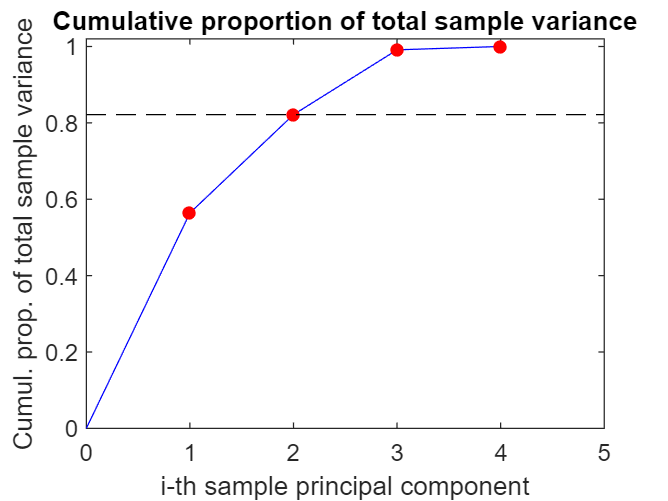

figure();
plot(0:n,[0; cumulprop], 'b-')
hold on
plot(1:n,cumulprop,'r.','MarkerSize',16)
xlim([0 n+1])
ylim([0 1.02])
plot(linspace(0,n+1,100),cumulprop(2)*ones(100),'k--') % The line representing
                                            % the cumulative proportion of
                                            % sample variance explained by
                                            % the first two princ. comp.
xlabel('i-th sample principal component')
ylabel('Cumul. prop. of total sample variance')
title('Cumulative proportion of total sample variance')


disp(sprintf('The first sample principal component explains %.3f%% of variability', 100*cumulprop(1)))

The first sample principal component explains 56.399% of variability


for(i=2:n)
    disp(sprintf('The first %d sample principal components explain %.3f%% of variability', i, 100*cumulprop(i)))
end

The first 2 sample principal components explain 82.146% of variability
The first 3 sample principal components explain 99.114% of variability
The first 4 sample principal components explain 100.000% of variability


The line is representing the cumulative proportion of sample variance explained by the first two princ. comp.

5. Find in MATLAB the loadings of the first two sample principal components. Include these values in the report and try to second an interpretation of these principal components.

The first 2 sample principal components explain 82% of variability in our dataset; we selected two as stated by the task but I will add the fact that with the third component a staggering 99% of variance is explained. we reverse the columns of matrix $P$.

for i = 1:n
    loadings(:,i) = P(:,end-i+1);
end

The loadings of the first principal component are:

loadings(:,1)

ans =    -0.9215
   -0.0277
    0.0208
    0.3869


Hence, the first principal component is:

$\mathbf y_1 = -0.92 \mathbf x_1 - 0.03\mathbf x_2 + 0.02\mathbf x_3 + 0.38 \mathbf x_4$.

The loadings of the second principal component are:

loadings(:,2)

ans =    -0.2666
    0.0886
    0.6912
   -0.6658


Hence, the second principal component is:

$\mathbf y_2 = -0.27 \mathbf x_1 + 0.09\mathbf x_2 + 0.69\mathbf x_3 - 0.66 \mathbf x_4 $.

6. Compute in MATLAB the scores of all the sample principal components. Then, draw those associated to the first two sample principal components, in the plane generated by the first two eigenvectors of the sample correlation matrix.

avg = mean(predictors)

avg =   301.7234  185.1907  969.2714  765.3499


for i = 1:m
    data_cen(i,:) = (predictors(i,:) - avg);
end
scores = data_cen*loadings;

plot:

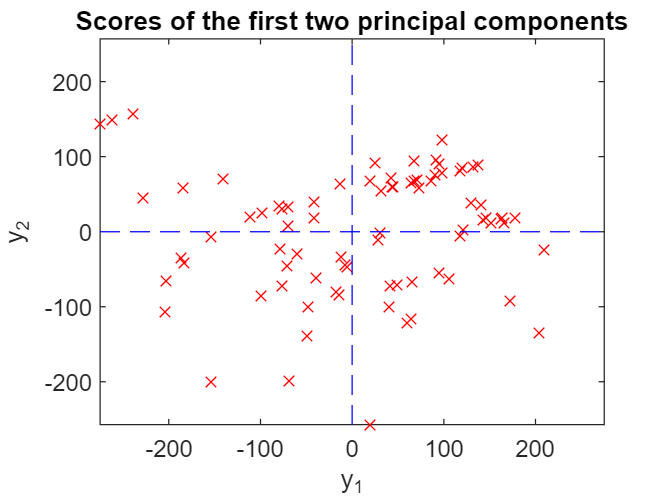

figure();
plot(scores(:,1), scores(:,2),'rx')
eps = 0.01;
xmax = max(abs(scores(:,1))) + eps; % Values to set the ranges of the axes. Add
ymax = max(abs(scores(:,2))) + eps; % eps to have some margin.
xlim([-xmax xmax])
ylim([-ymax ymax])
hold on
N = 100;
x = linspace(-xmax, xmax, N); 
y = linspace(-ymax, ymax, N);
plot(x,zeros(N),'b--')
plot(zeros(N),y,'b--')
xlabel('y_1')
ylabel('y_2')
title('Scores of the first two principal components')
hold off